# Week 4 exercise

% safety first
close all;
clear all;
clc;

### Confidence interval calculations

% N = sample size
N = 10;
% generate random number
myerr = rand(N,1)-.5;
noiselev=5.0;
signal=10.0;
% add noise to the signal
x=signal+noiselev*myerr;
disp(num2str(round(x,1)));

11.7
11.4
12.2
 9.9
  11
10.3
12.3
10.1
  11
   9


% sample mean and std
M=mean(x)

M = 10.8909

s=std(x)

s = 1.0588

% calculate the critical t value
CL=0.95;
alpha=1-CL;
df=N-1;
SE=s/sqrt(N-1);
tcrit=tinv(1-alpha/2,df);
dx = tcrit*SE;

% Monte carlo test
K=10000;
N=10;
CL=0.95;
alpha=1-CL;
df=N-1;
tcrit=tinv(1-alpha/2,df);

CI_correct = zeros(K,1);
for m=1:K
    myerr=rand(N,1)-.5;
    x=signal+noiselev*myerr;
    M=mean(x);
    s=std(x);
    SE=s/sqrt(N-1);
    dx=tcrit*SE;
    if (M-dx < signal) & (signal < M+dx)
        CI_correct(m)=1;
    end
end
disp(num2str(sum(CI_correct)/K))

0.9545


### Linear regression

close all;
clear all;

% read data
data=xlsread('ATL_MonMeanTemp_1879_2020.xls');
x=data(:,1);
y=data(:,10); % september
y(10:20)=NaN;

ind=(~isnan(y)) & (x > 1981) & (x < 2020);
c=cov(x(ind),y(ind));
a=c(1,2)/c(1,1);
b=mean(y(ind))-a*mean(x(ind));

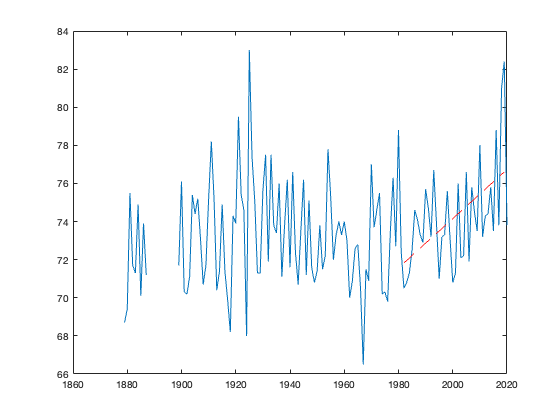

figure;
plot(x,y);
hold on;
plot(x(ind),a*x(ind)+b,'r--');
hold off;

r2=c(1,2)^2/c(1,1)/c(2,2);
disp(num2str([a,b,r2]));

0.1291498     -184.1457     0.2893425


% Matrix way: pseudo inverse
N=length(x(ind));
A=ones(N,2);
A(:,1)=x(ind);
xvec=pinv(A)*y(ind);
disp(num2str(xvec));

0.1291498
-184.1457


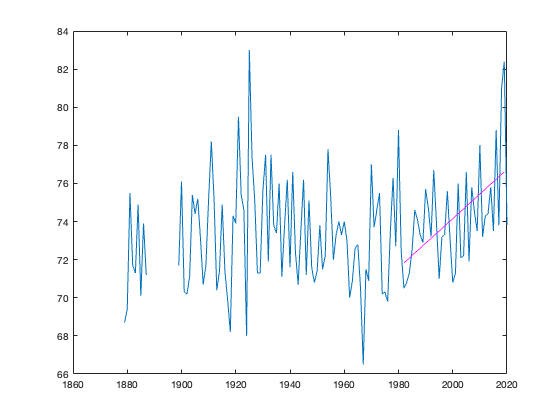

% plot again
plot(x,y);
hold on;
plot(x(ind),A*xvec,'m-');
hold off;

R2 = xvec(1)^2 * var(x(ind))/var(y(ind));
disp(['R2 value is ',num2str(R2)]);

R2 value is 0.28934
